M = 16;                     %Comment
k = log2(M);                %
n = 30000;                  %
numSamplePerSymbol = 1;     %

rng default;

rng('default') は、rand、randi および randn で使用される乱数発生器の設定を既定値に指定します。これにより、MATLAB を再起動したかのように、同じ乱数が生成されます。既定の設定は、seed が 0 のメルセンヌ・ツイスターです。

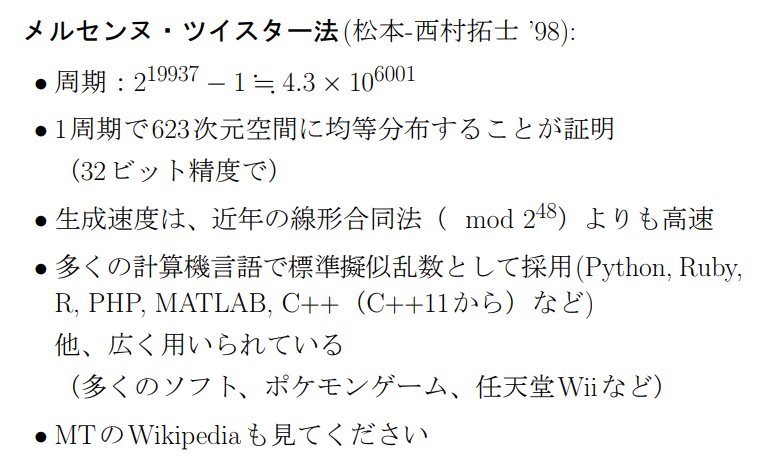

dataIn = randi([0,1],n,1); % 0 ~ 1 の間の値でランダムにn個出力。データのステップは1。

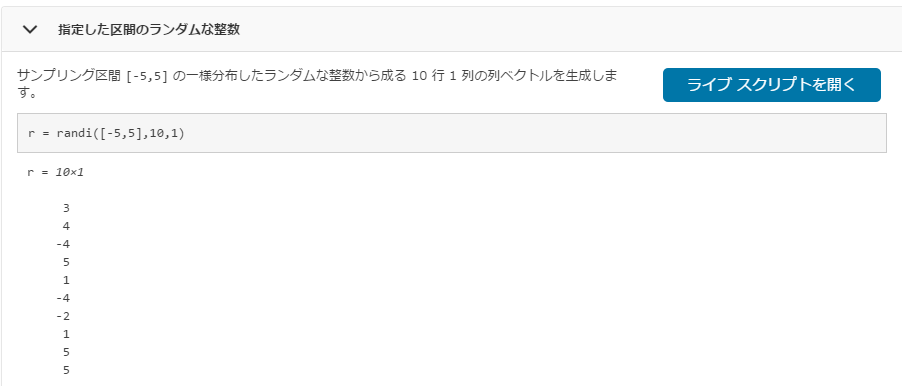

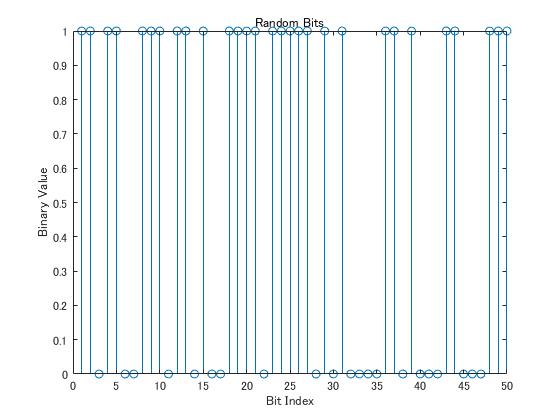

stem(dataIn(1:50)); %離散データ列のプロット
title('Random Bits');
xlabel('Bit Index');
ylabel('Binary Value');

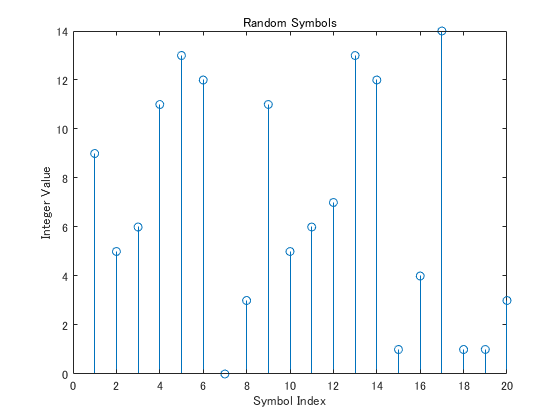

dataInMatrix = reshape(dataIn,length(dataIn)/k,k); %reshapeは次元変更関数：dataIn(30000行1列)を30000行k列に変換
dataSymbolsIn = bi2de(dataInMatrix); %2進数から10進数への変換

figure;
stem(dataSymbolsIn(1:20));
title('Random Symbols');
xlabel('Symbol Index');
ylabel('Integer Value');

dataMod = qammod(dataSymbolsIn,M,'bin');
dataModG = qammod(dataSymbolsIn,M); %シンボル順序のデフォルトはGray

EbN0 = 10;
snr = EbN0 + 10*log10(k) - 10*log10(numSamplePerSymbol)

snr = 16.0206

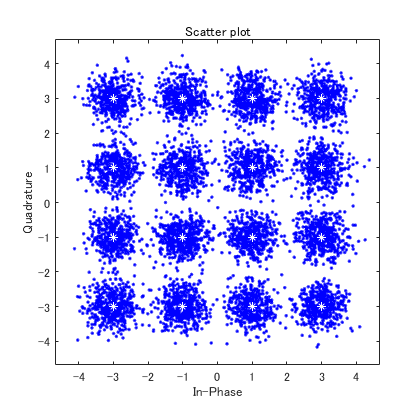


receivedSignal = awgn(dataMod,snr,'measured');
receivedSignalG = awgn(dataModG,snr,'measured');

sPlot1 = scatterplot(receivedSignal,1,0,'green.');
hold on
sPlot2 = scatterplot(dataMod,1,0,'black*',sPlot1);
sPlot1G = scatterplot(receivedSignalG,1,0,'b.');
hold on
sPlot2G = scatterplot(dataModG,1,0,'white*',sPlot1G);

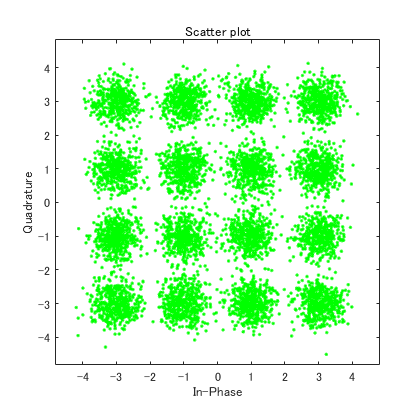

scatterplot(receivedSignal,1,0,'green.');
hold on

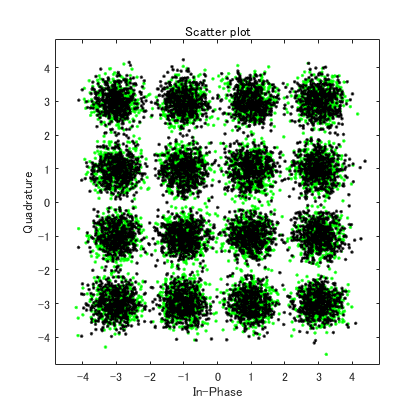

scatterplot(receivedSignalG,1,0,'black.',sPlot1);


dataSymbolsOut = qamdemod(receivedSignal,M,'bin');
dataSymbolsOutG = qamdemod(receivedSignalG,M);

dataOutMatrix = de2bi(dataSymbolsOut,k);
dataOut = dataOutMatrix(:);
dataOutMatrixG = de2bi(dataSymbolsOutG,k);
dataOutG = dataOutMatrixG(:);

[numErrors,ber] = biterr(dataIn,dataOut)

numErrors = 72

ber = 0.0024

fprintf('\nThe binary coding bit error rate = %5.2e, based on %d errors\n',ber,numErrors)


The binary coding bit error rate = 2.40e-03, based on 72 errors


[numErrorsG,berG] = biterr(dataIn,dataOutG)

numErrorsG = 40

berG = 0.0013

fprintf('\nThe binary coding bit error rate = %5.2e, based on %d errors\n',berG,numErrorsG)


The binary coding bit error rate = 1.33e-03, based on 40 errors


# **16-QAM のバイナリ シンボル マッピングのコンスタレーション**

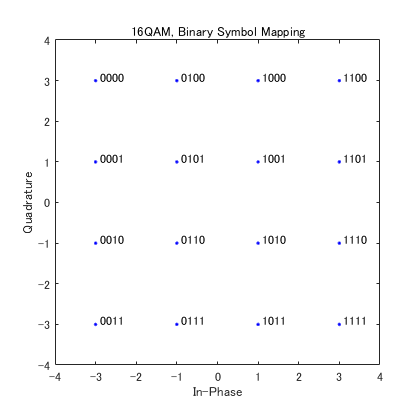

M = 16;
x1 = (0:15);
x = (0:15)';
y1 = qammod(x,M,'bin');
y2 = qammod(x,M);

scatterplot(y1);
text(real(y1)+0.1,imag(y1)+0.1,dec2bin(x));
title('16QAM, Binary Symbol Mapping');
axis([-4 4 -4 4])

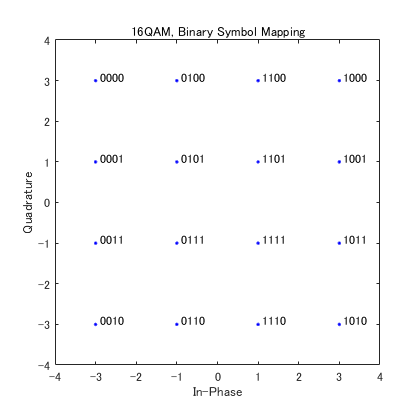

scatterplot(y2);
text(real(y2)+0.1,imag(y2)+0.1,dec2bin(x));
title('16QAM, Binary Symbol Mapping');
axis([-4 4 -4 4])

# **レイズド コサイン フィルターの作成**


M = 16;
k = log2(M);
numBits = 3e5;
numSamplePerSymbol = 4;

span = 10;
rolloff = 0.25;

rrcFilter = rcosdesign(rolloff,span,numSamplePerSymbol)

rrcFilter =    -0.0038   -0.0057   -0.0015    0.0064    0.0106    0.0050   -0.0091   -0.0213   -0.0188    0.0030    0.0327    0.0471    0.0265   -0.0275   -0.0852   -0.0994   -0.0321    0.1189    0.3109    0.4716    0.5342    0.4716    0.3109    0.1189   -0.0321   -0.0994   -0.0852   -0.0275    0.0265    0.0471    0.0327    0.0030   -0.0188   -0.0213   -0.0091    0.0050    0.0106    0.0064   -0.0015   -0.0057   -0.0038


%fvtool(rrcFilter,'Analysis','magnitude','impulse');
%fvtool(rrcFilter,'Analysis','impulse');
%fvtool(rrcFilter,'Analysis','info');
%fvtool(rrcFilter,'Analysis','step','grid','off','legend','on');

# **BER シミュレーション**

txSignal = upfirdn(dataMod,rrcFilter,numSamplePerSymbol,1)

txSignal =   -0.0038 - 0.0038i
  -0.0057 - 0.0057i
  -0.0015 - 0.0015i
   0.0064 + 0.0064i
   0.0144 + 0.0069i
   0.0107 - 0.0008i
  -0.0077 - 0.0106i
  -0.0278 - 0.0149i
  -0.0256 - 0.0044i
   0.0038 + 0.0137i


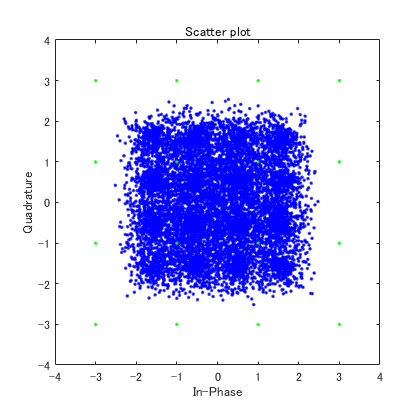

sPlot3 = scatterplot(txSignal(1:10000));
hold on
scatterplot(dataMod(1:1000),1,0,'green.',sPlot3)
axis([-4 4 -4 4]);